# Chapter 4, Section 4 (Part 1)

The goal of this activity is to show how we can write any linear transformation in matrix form. 

Suppose that $V$ and $W$ are finite dimensional vector spaces; $\text{dim}(V)=n$ and $\text{dim}(W)=m$. Let $B=\{\vec v_1\,\ \ldots,\ \vec v_n\}$ and $C=\{\vec w_1,\ \ldots,\ \vec w_m\}$ be ordered bases for $V$ and $W$ and let $T:\, V\rightarrow W$ be a linear transformation. 

Let $\vec v\in V$, then $\vec v=c_1\vec v_1+\cdots c_n\vec v_n$, so the coordinates of $\vec v$ relative to the basis $B$ are:


$$[\vec v]_B=\pmatrix{c_1\cr \vdots\cr c_n}$$


Now we will take the linear transform of $\vec v$.


$$\begin{array}{rcl}
T(\vec v)&=&T(c_1\vec v_1+\cdots+c_n\vec v_n)\\
T(\vec v)&=&c_1T(\vec v_1)+\cdots+c_nT(\vec v_n)
\end{array}$$


Because $T(\vec v_1),\ T(\vec v_2),\ \ldots,\ T(\vec v_n)$ are each elements of $W$, we can write:


$$\begin{array}{rcl}
T(\vec v_1)&=&a_{11}\vec w_1+a_{21}\vec w_2+\cdots+a_{m1}\vec w_m\\
T(\vec v_2)&=&a_{12}\vec w_1+a_{22}\vec w_2+\cdots+a_{m2}\vec w_m\\
\vdots & \vdots & \vdots\\
T(\vec v_n)&=&a_{1n}\vec w_1+a_{2n}\vec w_2+\cdots+a_{mn}\vec w_m
\end{array}$$


Hence, the coordinates of $T(\vec v_1),\ T(\vec v_2),\ \ldots,\ T(\vec v_n)$ with respect to the basis $C$ are:


$$\begin{array}{rcl}
[T(\vec v_1)]_C&=&\pmatrix{a_{11}\cr a_{21}\cr \vdots\cr a_{m1}}\\
[T(\vec v_2)]_C&=&\pmatrix{a_{12}\cr a_{22}\cr \vdots\cr a_{m2}}\\
\vdots\\
[T(\vec v_n)]_C&=&\pmatrix{a_{1n}\cr a_{2n}\cr \vdots\cr a_{mn}}
\end{array}$$


Now, we've proved that any coordinate transformation is a linear tranformation, so we can write:


$$\begin{array}{rcl}
[T(\vec v)]_C&=&[c_1T(\vec v_1)+c_2T(\vec v_2)+\cdots+c_nT(\vec v_n)]_C\\
[T(\vec v)]_C&=&c_1[T(\vec v_1)]_C+c_2[T(\vec v_2)]_C+\cdots+c_n[T(\vec v_n)]_C
\end{array}$$


This can also be written matrix form.


$$\begin{array}{rcl}
[T(\vec v)]_C&=&\pmatrix{[T[\vec v_1]_C & [T(\vec v_2)]_C & \cdots & [T(\vec v_n)]_C}\pmatrix{c_1\cr c_2\cr \vdots\cr c_n}
\end{array}$$


Now, recall that above we set 


$$[\vec v]_B=\pmatrix{c_1\cr c_2\cr \vdots\cr c_n}$$


so this last statement can be written as:


$$[T(\vec v)]_C=\pmatrix{[T(\vec v_1)]_C & [T(\vec v_2)]_C & \cdots & [T(\vec v_n)]_C}[\vec v]_B$$


Our author uses this notation for our transition matrix


$$[T]^C_B= \pmatrix{[T(\vec v_1)]_C & [T(\vec v_2)]_C & \cdots & [T(\vec v_n)]_C}$$


then writes:


$$[T(\vec v)]_C=[T]_B^C\ [\vec v]_B$$


But we can also use a symbolism that we are familiar with:


$$[T(\vec v)]_C=[T]_{C\leftarrow B}\ [\vec v]_B$$


Let's do an example to see if this works.

# Example #1

Let $T:\mathbb R^2\rightarrow \mathbb R^2$ be a linear transformation defined by:


$$T\left(\pmatrix{x\cr y}\right)=\pmatrix{x+y\cr 2x-y}$$


Let $B$ and $C$ represent ordered bases for $\mathbb R^2$ and $\mathbb R^2$ respectively.


$$B=\left\{\pmatrix{-1\cr 1},\ \pmatrix{2\cr 1}\right\}\qquad\text{and}\qquad C=\left\{\pmatrix{-2\cr 1},\ \pmatrix{1\cr 1}\right\}$$


Find the matrix $[T]_B^C$, or equivalently, the matrix $[T]_{C\leftarrow B}$ (feel free to use either notation).

**Solution:** 

**Step 1: **The first step is to compute $T(\vec b_1)$ and $T(\vec b_2)$, where $B=\{\vec b_1,\ \vec b_2\}$. Using the definition


$$T\left(\pmatrix{x\cr y}\right)=\pmatrix{x+y\cr 2x-y}$$


we can write


$$T\left(\pmatrix{-1\cr 1}\right)=\pmatrix{-1+1\cr 2(-1)-1}=\pmatrix{0\cr -3}$$


and:


$$T\left(\pmatrix{2\cr 1}\right)=\pmatrix{2+1\cr 2(2)-1}=\pmatrix{3\cr 3}$$


Let's check this with Matlab. Note that our transformation function can be written as:


$$T\left(\pmatrix{x\cr y}\right)=\pmatrix{1 & 1\cr 2 & -1}\pmatrix{x\cr y}$$


So we will create the following autonomous function.

A=[1 1;2 -1];
T=@(x) A*x;

Then we will enter our basis vectors for $B$ and $C$.

b1=[-1;1]; b2=[2;1];
c1=[-2;1]; c2=[1;1];

Now we will compute $T(\vec b_1)$ and $T(\vec b_2)$.

T(b1)

ans =      0
    -3


T(b2)

ans =      3
     3


These are the same as our hand-calculated answers. 

**Step 2: **Now we have to find the coordinate vectors $[T(\vec b_1)]_C$ and $[T(\vec b_2)]_C$ with respect to the basis $C$,  which will be the columns of our matrix $[T]_{C\leftarrow B}$. Let's do $[T(\vec b_1)]_C$ first.


$$\begin{array}{rcl}
[T(\vec b_1)]_C&=&d_1\vec c_1+d_2\vec c_2\\
\pmatrix{0\cr -3}&=&d_1\pmatrix{-2\cr 1}+d_2\pmatrix{1\cr 1}
\end{array}$$


The augmented matrix for this system is:


$$\pmatrix{-2 & 1 & 0\cr 1 & 1 & -3}\ \matrix{R_1\leftrightarrow R_2\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & -3\cr -2 & 1 & 0}\ \matrix{~\cr R_2+2R_1}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & -3\cr 0 & 3 & -6}$$
 

Continuing:


$$\pmatrix{1 & 1 & -3\cr 0 & 3 & -6}\ \matrix{~\cr (1/3)R_2}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & -3\cr0 & 1 & -2}\ \matrix{ R_1-R_2\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 0 & -1\cr 0 & 1 & -2}$$


We can check this with Matlab. Note that we started with the following augmented matrix.


$$\pmatrix{\vec c_1 &\vec c_2 & T(\vec b_1)}$$


rref([c1,c2,T(b1)])

$$ans = \left(\begin{array}{ccc} 1 & 0 & -1\\ 0 & 1 & -2 \end{array}\right)$$

Same answer. So we have determined that:


$$[T(\vec b_1)]_C=\pmatrix{-1\cr -2}$$


Now we have to determine $[T(\vec b_2)]_C$.


$$\begin{array}{rcl}
[T(\vec b_2)]_C&=&d_1\vec c_1+d_2\vec c_2\\
\pmatrix{3\cr 3}&=&d_1\pmatrix{-2\cr 1}+d_2\pmatrix{1\cr 1}
\end{array}$$


The augmented matrix for this system is:


$$\pmatrix{-2 & 1 & 3\cr 1 & 1 & 1}\ \matrix{R_1\leftrightarrow R_2\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & 3\cr -2 & 1 & 3}\ \matrix{~\cr R_2+2R_1}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & 3\cr 0 & 3 & 9}$$
 

Continuing:


$$\pmatrix{1 & 1 & 3\cr 0 & 3 & 9}\ \matrix{~\cr (1/3)R_2}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & 3\cr 0 & 1 & 3}\ \matrix{ R_1-R_2\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 0 & 0\cr 0 & 1 & 3}$$


We can check this with Matlab. Note that we started with the following augmented matrix.


$$\pmatrix{\vec c_1 &\vec c_2 & T(\vec b_2)}$$


rref([c1,c2,T(b2)])

ans =      1     0     0
     0     1     3


Same answer. So we have determined that:


$$[T(\vec b_2)]_C=\pmatrix{0\cr 3}$$


Therefore, the matrix for our linear transformation is:


$$\begin{array}{rcl}
[T]_{C\leftarrow B}&=&\pmatrix{[T(\vec b_1)]_C & [T(\vec b_2)]_C}\\
[T]_{C\leftarrow B}&=&\pmatrix{-1 & 0\cr -2 & 3}
\end{array}$$


# Was that too much work?

Some might be moaning that we did duplicate row reductions twice to determine $[T]_{C\leftarrow B}$, which is true. To find $[T(\vec b_1)]_C$, we row reduced $\pmatrix{\vec c_1 & \vec c_2 & T(\vec b_1)}$. To find $[T(\vec b_2)]_C$, we row reduced $\pmatrix{\vec c_1 & \vec c_2 & T(\vec b_2)}$. What if we had done them both at the same time by row reducing $\pmatrix{\vec c_1 & \vec c_2 & T(\vec b_1) & T(\vec b_2)}$? Let's try it and see what happens.


$$\pmatrix{\vec c_1 & \vec c_2 & T(\vec b_1) & T(\vec b_2)}=\pmatrix{-2 & 1 & 0 & 3\cr 1 & 1 & -3 & 3}$$


Let's row reduce.


$$\pmatrix{-2 & 1 & 0 & 3\cr 1 & 1 & -3 & 3}\ \matrix{R_1\leftrightarrow R_2\cr ~}\qquad\longrightarrow\qquad \pmatrix{1 & 1 & -3 & 3\cr -2 & 1 & 0 & 3}\ \matrix{~\cr R_2+2R_1}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & -3 & 3\cr 0 & 3 & -6 & 9}$$


Continue.


$$\pmatrix{1 & 1 & -3 & 3\cr 0 & 3 & -6 & 9}\ \matrix{~\cr (1/3)R_2}\qquad\longrightarrow\qquad \pmatrix{1 & 1 & -3 & 3\cr 0 & 1 & -2 & 3}\ \matrix{ R_1-R_2\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 0 & -1 & 0\cr 0 & 1 & -2 & 3}$$


And we can easily check this with Matlab.

M=rref([c1,c2,T(b1),T(b2)])

M =      1     0    -1     0
     0     1    -2     3


Same answer. And we can strip out the last two columns and store them in $[T]_{C\leftarrow B}$.

TCB=M(:,[3,4])

TCB =     -1     0
    -2     3


Wow! This means that the easy way to find the matrix for our linear transformation is to create an augmented matrix


$$\pmatrix{\vec c_1 & \vec c_2 & \cdots & \vec c_m & T(\vec b_1) & T(\vec b_2) & \cdots & T(\vec b_n)}$$


and row reduce it. The result will be $[\ I \ |\ [T]_{C\leftarrow B}\ ]$.  We had a lot of explanatory steps in this Example #1, but here is some complete code for the process.

A=[1 1;2 -1];
T=@(x) A*x;
b1=[-1;1]; b2=[2;1];
c1=[-2;1]; c2=[1;1];
M=rref([c1,c2,T(b1),T(b2)]);
TCB=M(:,[3,4])

TCB =     -1     0
    -2     3


Really quick! :-)

# Does This Process Work?

Let's create a graphing grid for $\mathbb R^2$ relative to the basis $B=\left\{\pmatrix{-1\cr 1},\ \pmatrix{2\cr 1}\right\}$ and add the vector $\vec v=\pmatrix{2\cr 4}$.

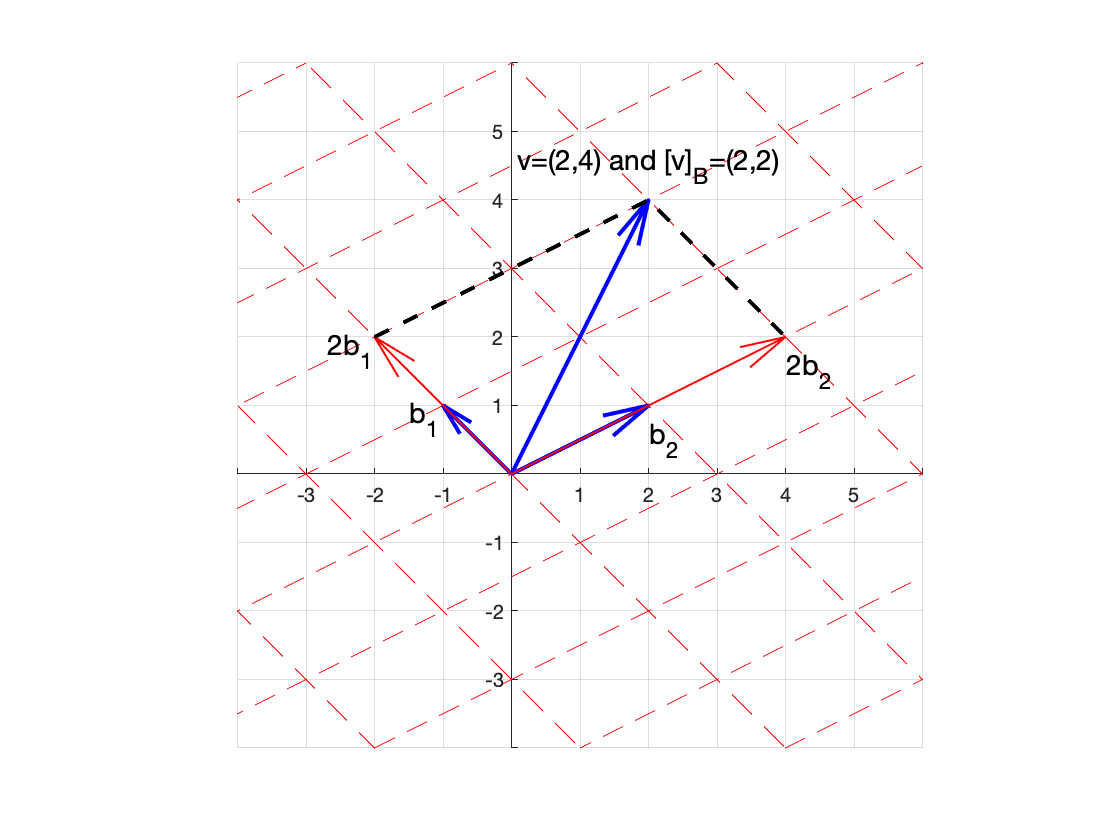

figure, hold on
t=linspace(-10,10);
for k=-10:10
    plot(-k+2*t,k+t,'r--')
    plot(2*k-t,k+t,'r--')
end
quiver(0,0,2,1,0,'LineWidth',2,'Color','b','MaxHeadSize',1)
quiver(0,0,-1,1,0,'LineWidth',2,'Color','b','MaxHeadSize',2)
quiver(0,0,2,4,0,'LineWidth',2,'Color','b','MaxHeadSize',0.5)
quiver(0,0,4,2,0,'LineWidth',1,'Color','r','MaxHeadSize',0.5)
quiver(0,0,-2,2,0,'LineWidth',1,'Color','r','MaxHeadSize',1)
line([-2 2 4],[2 4 2],'LineStyle','--','LineWidth',2,'Color','k')
axis equal
axis([-4,6,-4,6])
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
text(-1.5,0.8,'b_1','FontSize',14)
text(-2.7,1.8,'2b_1','FontSize',14)
text(2,0.5,'b_2','FontSize',14)
text(4,1.5,'2b_2','FontSize',14)
text(2,4.5,'v=(2,4) and [v]_B=(2,2)','HorizontalAlignment','center','FontSize',14)
hold off

Note that the vector $\vec v=(2,4)$ is in standard coordinates, but in terms of the basis $B=\{\vec b_1,\ \vec b_2\}$, its coordinates are $[\vec v]_B=(2,2)$. Now, our linear transformation is 


$$T\left(\pmatrix{x\cr y}\right)=\pmatrix{x+y\cr 2x-y}$$


so let's see where it sends the vector $\vec v=(2,4)$.


$$\begin{array}{rcl}
T\left(\pmatrix{2\cr 4}\right)&=&\pmatrix{2+4\cr 2(2)-4}\\
T\left(\pmatrix{2\cr 4}\right)&=&\pmatrix{6\cr 0}
\end{array}$$


Using the matrix form of our linear transformation, we can calculate $[T(\vec v)]_C$.


$$\begin{array}{rcl}
[T(\vec v)]_C&=&[T]_{C\leftarrow B}\ [\vec v]_B\\
\left[T\left(\pmatrix{2\cr 4}\right)\right]_C&=&\pmatrix{-1 & 0\cr -2 & 3}\pmatrix{2\cr 2}\\
\left[\pmatrix{6\cr 0}\right]_C&=&\pmatrix{-2\cr 2}
\end{array}$$


Now, is this correct? Let's create a graphing grid for $\mathbb R^2$ relative to the basis $C=\left\{\pmatrix{-2\cr 1},\ \pmatrix{1\cr 1}\right\}$ and add the vector $T(\vec v)=\pmatrix{6\cr 0}$.

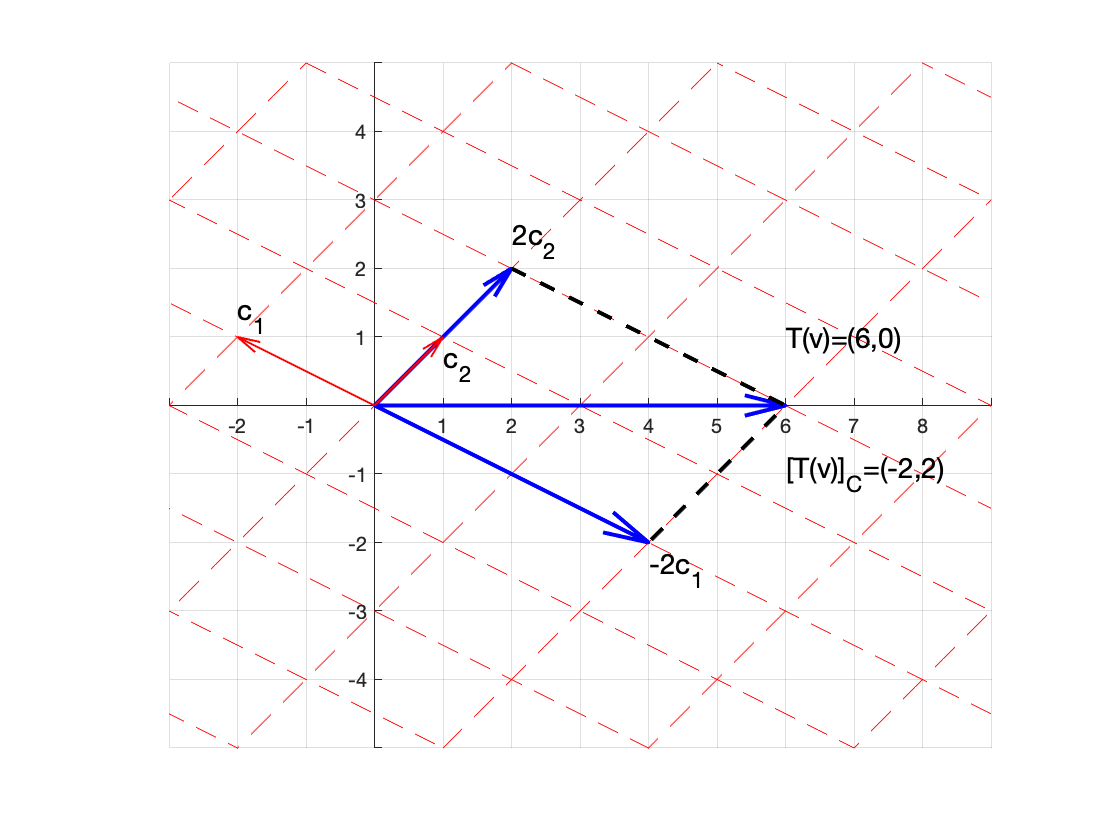

figure, hold on
t=linspace(-10,10);
for k=-10:10
    plot(k-2*t,k+t,'r--')
    plot(-2*k+t,k+t,'r--')
end
quiver(0,0,4,-2,0,'LineWidth',2,'Color','b','MaxHeadSize',0.5)
quiver(0,0,2,2,0,'LineWidth',2,'Color','b','MaxHeadSize',0.7)
quiver(0,0,6,0,0,'LineWidth',2,'Color','b','MaxHeadSize',0.3)
quiver(0,0,-2,1,0,'LineWidth',1,'Color','r','MaxHeadSize',0.5)
quiver(0,0,1,1,0,'LineWidth',1,'Color','r','MaxHeadSize',1)
line([2,6,4],[2,0,-2],'LineStyle','--','LineWidth',2,'Color','k')
axis equal
axis([-3,9,-5,5])
xticks(-3:9)
yticks(-5:5)
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
text(-2,1.3,'c_1','FontSize',14)
text(4,-2.4,'-2c_1','FontSize',14)
text(1,0.6,'c_2','FontSize',14)
text(2,2.4,'2c_2','FontSize',14)
text(6,1,'T(v)=(6,0)','HorizontalAlignment','left','FontSize',14)
text(6,-1,'[T(v)]_C=(-2,2)','HorizontalAlignment','left','FontSize',14)

hold off

Note that the vector $T(\vec v)=(6,0)$ is in standard coordinates, but in terms of the basis $C=\{\vec c_1,\ \vec c_2\}$, its coordinates are $[T(\vec v)]_C=(-2,2)$.  This is clear visual evidence that this matrix form of a linear transformation works.

# Example #2

Let $T:\mathbb R^2\rightarrow \mathbb R^3$ be defined by


$$T\left(\pmatrix{x_1\cr x_2}\right)=\pmatrix{x_1+x_2\cr x_1-x_2\cr x_2}$$


and let


$$B=\left\{\pmatrix{1\cr 1},\ \pmatrix{2\cr 1}\right\}\qquad\text{and}\qquad C=\left\{\pmatrix{1\cr 1\cr 1},\ \pmatrix{1\cr 1\cr 0},\ \pmatrix{1\cr 0\cr 0}\right\}$$


be ordered bases for $\mathbb R^2$ and $\mathbb R^3$. Determine this transformation in matrix form, finding $[T]_{C\leftarrow B}$. Next, let $\vec v=\pmatrix{2\cr -3}$ and determine $T(\vec v)$ using a direct computation and using the matrix representation.

**Solution: **The first step is to calculate $T(\vec b_1)$ and $T(\vec b_2)$, so


$$T(\vec b_1)=T\left(\pmatrix{1\cr 1}\right)=\pmatrix{1+1\cr 1-1\cr 1}=\pmatrix{2\cr 0\cr 1}$$


and:


$$T(\vec b_2)=T\left(\pmatrix{2\cr 1}\right)=\pmatrix{2+1\cr 2-1\cr 1}=\pmatrix{3\cr 1\cr 1}$$


Note that we can write our linear transformation in matrix form.


$$T\left(\pmatrix{x_1\cr x_2}\right)=\pmatrix{x_1+x_2\cr x_1-x_2\cr x_2}=\pmatrix{1 & 1\cr 1 & -1\cr 0 & 1}\pmatrix{x_1\cr x_2}$$


Let's check our computations with Matlab.

A=[1 1;1 -1;0 1];
T=@(x) A*x;
b1=[1;1]; b2=[2;1];
c1=[1;1;1]; c2=[1;1;0]; c3=[1;0;0];
T(b1)

ans =      2
     0
     1


T(b2)

ans =      3
     1
     1


Same as our hand-calculations above. Now, we have to determine $[T(\vec b_1)]_C$ and $[T(\vec b_2)]_C$. We will use our quick shortcut that we introduced in Example #1. We first set up


$$\pmatrix{\vec c_1 & \vec c_2 & \vec c_3 & T(\vec b_1) & T(\vec b_2)}$$


which is:


$$\pmatrix{1 & 1 & 1 & 2 & 3\cr 1 & 1 & 0 & 0 & 1\cr 1 & 0 & 0 & 0 & 1}$$


and we row reduce.


$$\pmatrix{1 & 1 & 1 & 2 & 3\cr 1 & 1 & 0 & 0 & 1\cr 1 & 0 & 0 & 0 & 1}\ \matrix{~\cr R_2-R_1\cr R_3-R_1}\qquad\longrightarrow\qquad \pmatrix{1 & 1 & 1 & 2 & 3\cr 0 & 0 & -1 & -2 & -2\cr 0 & -1 & -1 & -1 & -2}\ \matrix{~\cr R_2\leftrightarrow R_3\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & 1 & 2 & 3\cr 0 & -1 & -1 & -1 & -2\cr 0 & 0 & -1 & -2 & -2}$$


Continue.


$$\pmatrix{1 & 1 & 1 & 2 & 3\cr 0 & -1 & -1 & -1 & -2\cr 0 & 0 & -1 & -2 & -2}\ \matrix{~\cr-1R_2\cr -1R_3}\qquad\longrightarrow\qquad \pmatrix{1 & 1 & 1 & 2 & 3\cr 0 & 1 & 1 & 1 & 2\cr 0 & 0 & 1 & 2 & 2}\ \matrix{R_1-R_3\cr R_2-R_3\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & 0 & 0 & 1\cr 0 & 1 & 0 & -1 & 0\cr 0 & 0 & 1 & 2 & 2}$$


And finish.


$$\pmatrix{1 & 1 & 0 & 0 & 1\cr 0 & 1 & 0 & -1 & 0\cr 0 & 0 & 1 & 2 & 2}\ \matrix{R_1-R_2\cr ~\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 0 & 0 & 1 & 1\cr 0 & 1 & 0 & -1 & 0\cr 0 & 0 & 1 & 2 & 2}$$


Lot of work. Let's check it with Matlab.

M=rref([c1, c2, c3, T(b1), T(b2)])

M =      1     0     0     1     1
     0     1     0    -1     0
     0     0     1     2     2


This now has the form $[\ I\ |\ [T]_{C\leftarrow B}\ ]$, so we capture the last two columns for $[T]_{C\leftarrow B}$.

TCB=M(:,[4,5])

TCB =      1     1
    -1     0
     2     2


That agrees with our hand-calculations so we have found that


$$[T]_{C\leftarrow B}=\pmatrix{1 & 1\cr -1 & 0\cr 2 & 2}$$


Now, we were asked to show that this works for the vector $\vec v=\pmatrix{2\cr -3}$. Let's use the definition


$$T\left(\pmatrix{x_1\cr x_2}\right)=\pmatrix{x_1+x_2\cr x_1-x_2\cr x_2}$$


to determine $T\left(\pmatrix{2\cr -3}\right)$ directly.


$$T\left(\pmatrix{2\cr -3}\right)=\pmatrix{2+(-3)\cr 2-(-3)\cr -3}=\pmatrix{-1\cr 5\cr -3}$$


We can check this with Matlab.

v=[2;-3];
T(v)

ans =     -1
     5
    -3


Same answer. Next, to calculate $[T(\vec v)]_C$ using $[T(\vec v)]_C=[T]_{C\leftarrow B}\ [\vec v]_B$ we first have to calculate $[\vec v]_B$; that is, we have two determine the coordinates realative to the basis $B$ using:


$$\begin{array}{rcl}
\vec v&=&d_1\vec b_1+d_2\vec b_2\\
\pmatrix{2\cr -3}&=&d_1\pmatrix{1\cr 1}+d_2\pmatrix{2\cr 1}
\end{array}$$


Set up the augmented matrix for this system and row reduce.


$$\pmatrix{1 & 2 & 2\cr 1 & 1 & -3}\ \matrix{~\cr R_2-R_1}\quad\longrightarrow\quad \pmatrix{1 & 2 & 2\cr 0 & -1 & -5}\ \matrix{~\cr -1R_2}\quad\longrightarrow\quad\pmatrix{1 & 2 & 2\cr 0 & 1 & 5}\ \matrix{R_1-2R_2\cr ~}\quad\longrightarrow\quad\pmatrix{1 & 0 & -8\cr 0 & 1 & 5}$$


Therefore, $[\vec v]_B=(-8,5)$. We can check this with Matlab.

v=[2;-3];
M=rref([b1,b2,v])

M =      1     0    -8
     0     1     5


vB=M(:,3)

vB =     -8
     5


Same answer. Now we can compute $[T(\vec v)]_C$.


$$\begin{array}{rcl}
[T(\vec v)]_C&=&[T]_{C\leftarrow B}\ [\vec v]_B\\
[T(\vec v)]_C&=&\pmatrix{1 & 1\cr -1 & 0\cr 2 & 2}\pmatrix{-8\cr 5}\\
[T(\vec v)]_C&=&\pmatrix{-3\cr 8\cr -6}
\end{array}$$


We can check this with Matlab.

TvC=TCB*vB

TvC =     -3
     8
    -6


Same answer. Now, let's put this in standard coordinates.


$$\begin{array}{rcl}
T(\vec v)&=&-3\pmatrix{1\cr 1\cr 1}+8\pmatrix{1\cr 1\cr 0}-6\pmatrix{1\cr 0\cr 0}\\
T(\vec v)&=&\pmatrix{-1\cr 5\cr -3}
\end{array}$$


Now, because


$$-3\pmatrix{1\cr 1\cr 1}+8\pmatrix{1\cr 1\cr 0}-6\pmatrix{1\cr 0\cr 0}=\pmatrix{1 & 1 & 1\cr 1 & 1 & 0\cr 1 & 0 & 0}\pmatrix{-3\cr 8\cr -6}$$


we  can check this with Matlab as follows.

[c1, c2, c3]*TvC

ans =     -1
     5
    -3


Same answer that we got above directly. We are done. :-)